# ESEMPIO TEST DI DIAGNOSTICA "SOLLEVAMENTO A VUOTO"

In questo esempio si descrive come vengono utilizzate le principali funzioni per eseguire il test di diagnostica.

All'inizio il segnale nominale e il segnale acquisito grezzi vengono caricati in memoria.

## Carica in memoria il segnale nominale e il segnale acquisito

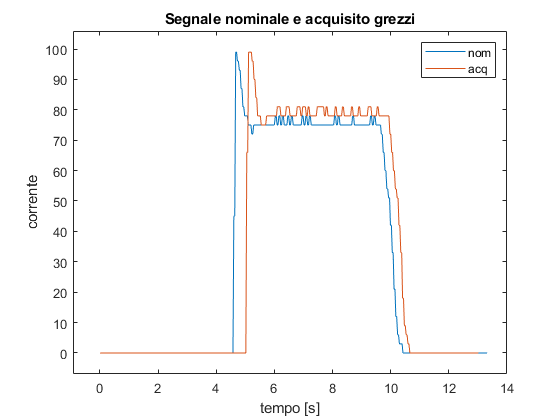

load('DATI_sv_0kg_5s.mat') % usato come segnale nominale in questo esempio
load('DATI_sv_22kg_5s.mat') % usato come segnale acquisito in questo esempio

% Plot dei dati grezzi acquisiti dall'inverter
figure
plot(DATI_sv_0kg_5s(:,1),DATI_sv_0kg_5s(:,2))
hold on
plot(DATI_sv_22kg_5s(:,1),DATI_sv_22kg_5s(:,2))
title('Segnale nominale e acquisito grezzi')
xlabel('tempo [s]')
ylabel('corrente')
legend('nom','acq')
axis padded

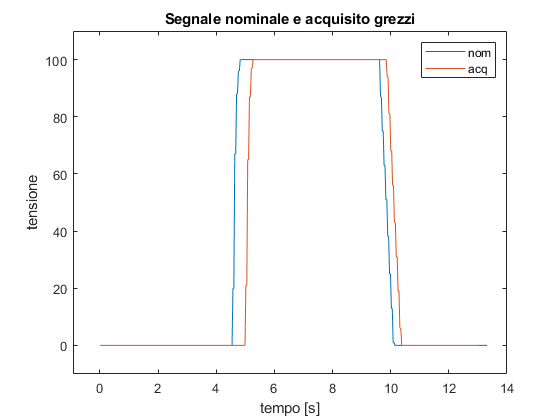


figure
plot(DATI_sv_0kg_5s(:,1),DATI_sv_0kg_5s(:,3))
hold on
plot(DATI_sv_22kg_5s(:,1),DATI_sv_22kg_5s(:,3))
title('Segnale nominale e acquisito grezzi')
xlabel('tempo [s]')
ylabel('tensione')
legend('nom','acq')
axis padded

## Ricampionamento dei due segnali a frequenza fissa

Dal momento che il campionamento del segnale nominale potrebbe non essere costante questo viene ricampionato alla sua frequenza di campionamento media.

Analogamente il segnale acquisito viene ricampionato alla stessa frequenza di campionamento del segnale nominale per ottenere due segnali confrontabili.

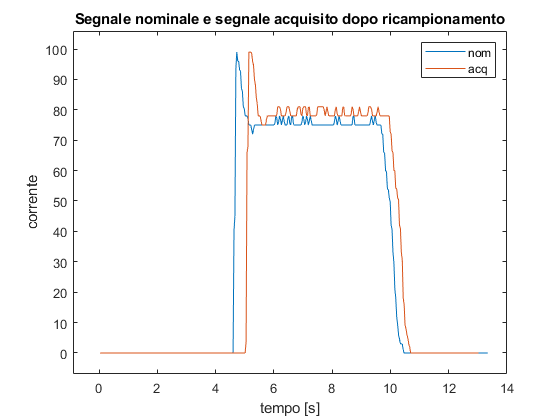

% Ricampiono il segnale nominale ad una frequenza di campionamento fissa 
% pari alla frequenza di acquisizione media e salvo il risultato in una
% struttura dati
Sn = ricampionaSegnale(DATI_sv_0kg_5s(:,2), DATI_sv_0kg_5s(:,1),0);

% Ricampiono il segnale acquisito ad una frequenza di campionamento fissa
% uguale a quella usata per il segnale nominale e salvo il risultato in una
% struttura dati
Sa = ricampionaSegnale(DATI_sv_22kg_5s(:,2), DATI_sv_22kg_5s(:,1),Sn.f);

% Plot dei due segnali dopo ricampionamento
figure
plotSegnale(Sn);
hold on
ylabel('corrente')
plotSegnale(Sa);
title('Segnale nominale e segnale acquisito dopo ricampionamento')
legend('nom','acq')
axis padded

## Elaborazione del segnale nominale

Il segnale nominale ha al suo inizio e alla sua fine delle acquisizioni non significative per il test. Il segnale utile viene quindi identificato e tagliato dal resto.

Dal momento che il segnale nominale non cambia i risultati dell'elaborazione vengono salvati per essere riutilizzati immediatamente nei prossimi test senza necessità di ripetere queste operazioni

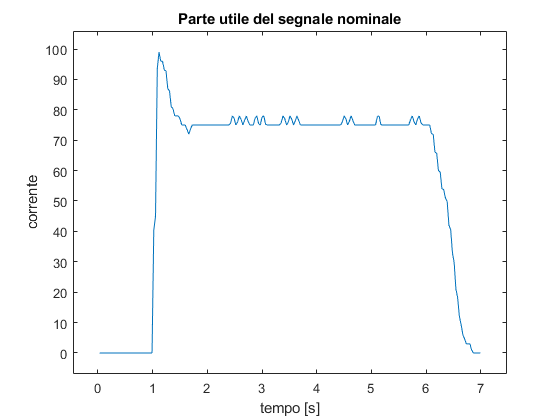

% Parametri per elaborazione del segnale nominale
n_d = 8; % [2,8] ordine del filtro FIR usato per calcolare la derivata prima
inizio_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare l'inizio del segnale utile
fine_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare la fine del segnale utile
margine_inizio = 1; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato
margine_fine = 1; % [s] margine di tempo aggiunto alla fine del segnale utile identificato

Sn_t = tagliaSegnaleUtile_sv(Sn,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);

% Plot del segnale utile identificato e ritagliato
figure
plotSegnale(Sn_t);
title('Parte utile del segnale nominale')
ylabel('corrente')
axis padded

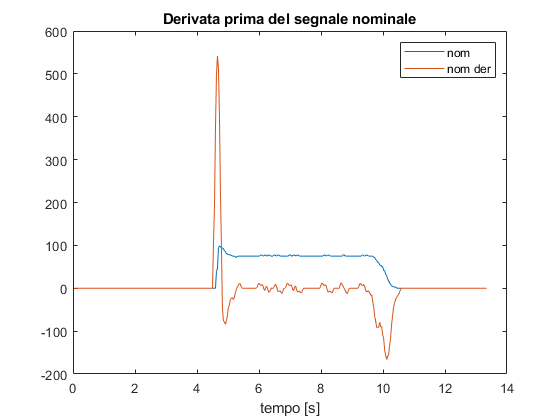


% L'inizio e la fine del segnale utile sono identificati nella funzione precedente analizzando i
% picchi della derivata prima del segnale
Sn_d = derivaSegnale(Sn,n_d); % (calcolo della derivata a solo scopo descrittivo)

% Il pratica questo segnale verrà salvato per poter essere riutilizzato
% quando serve senza bisogno di ripetere le elaborazioni
% "save(Sn_t);"

% Plot della derivata prima i cui picchi sono usati per l'identificazione del segnale utile
figure
plotSegnale(Sn);
hold on
plotSegnale(Sn_d);
title('Derivata prima del segnale nominale')
legend('nom','nom der')

## Elaborazione del segnale acquisito

Il segnale acquisito ha al suo inizio e alla sua fine delle acquisizioni non significative per il test. Il segnale utile viene quindi identificato e tagliato dal resto.

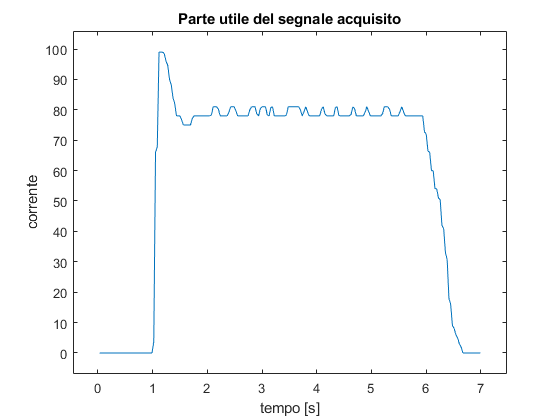

% Parametri per elaborazione del segnale acquisito
n_d = 8; % [2,8] ordine del filtro FIR usato per calcolare la derivata prima
inizio_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare l'inizio del segnale utile
fine_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare la fine del segnale utile
margine_inizio = 1; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato
margine_fine = 1; % [s] margine di tempo aggiunto alla fine del segnale utile identificato

Sa_t = tagliaSegnaleUtile_sv(Sa,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);

% Plot del segnale utile identificato e ritagliato
figure
plotSegnale(Sa_t);
title('Parte utile del segnale acquisito')
ylabel('corrente')
axis padded

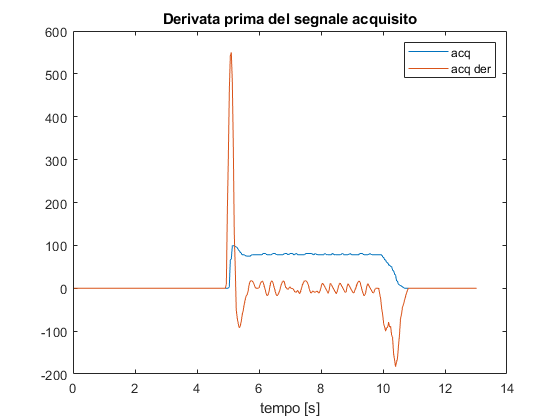


% L'inizio e la fine del segnale utile sono identificati nella funzione precedente analizzando i
% picchi della derivata prima del segnale
S_d = derivaSegnale(Sa,n_d); % (calcolo della derivata a solo scopo descrittivo)

% Plot della derivata prima i cui picchi sono usati per l'identificazione del segnale utile
figure
plotSegnale(Sa);
hold on
plotSegnale(S_d);
title('Derivata prima del segnale acquisito')
legend('acq','acq der')

## Calcolo indice "Minimo Errore Quadratico Medio"

Viene calcolato un indicatore di somiglianza tra il segnale nominale e il segnale acquisito. Tale indicatore determina lo stato di salute del mezzo e la sua idoneità ad essere utilizzato.

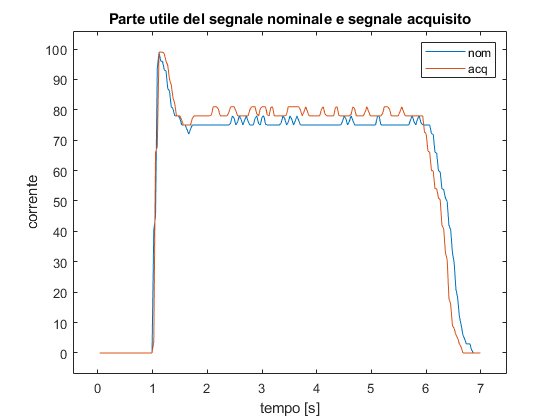

% Plot delle parte utile identificata del segnale nominale e segnale acquisito 
figure
plotSegnale(Sn_t);
hold on
plotSegnale(Sa_t);
title('Parte utile del segnale nominale e segnale acquisito')
ylabel('corrente')
legend('nom','acq')
axis padded

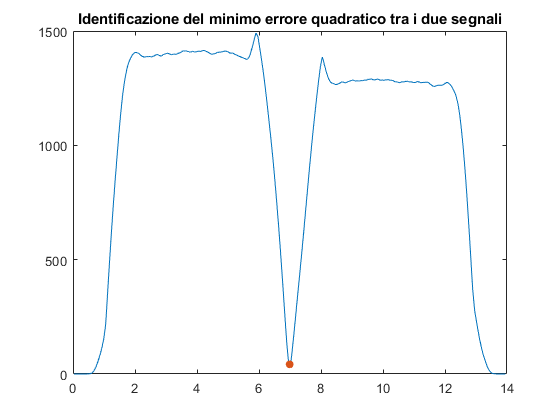

ind = 42.1689


% Calcolo dell'indice di correlaizione tra i due segnali, minore è l'indice
% maggiore è la somiglianza tra i due segnali
ind = Ind_minErroreQuadraticoMedio_sv(Sn_t,Sa_t)


% In base a una soglia si determina se il mezzo su cui è eseguito il test è
% idoneo ad essere utilizzato
ind_lim = 40;

if ind<ind_lim
    sprintf('Test superato')
else
    sprintf('Test fallito')
end

ans = 'Test fallito'